h=0.01;
alpha=[0.8,0.7];
param=[1,3];
y0=[1.2;2.8];
f_fun=@(t,y,par)([par(1)-(par(2)+1)*y(1)+y(1)^2*y(2); par(2)*y(1)-y(1)^2*y(2)]);
J_fun=@(t,y,par)([-(par(2)+1)+2*y(1)*y(2),y(1)^2;par(2)-2*y(1)*y(2),-y(1)^2]);
t0=0;
T=100;

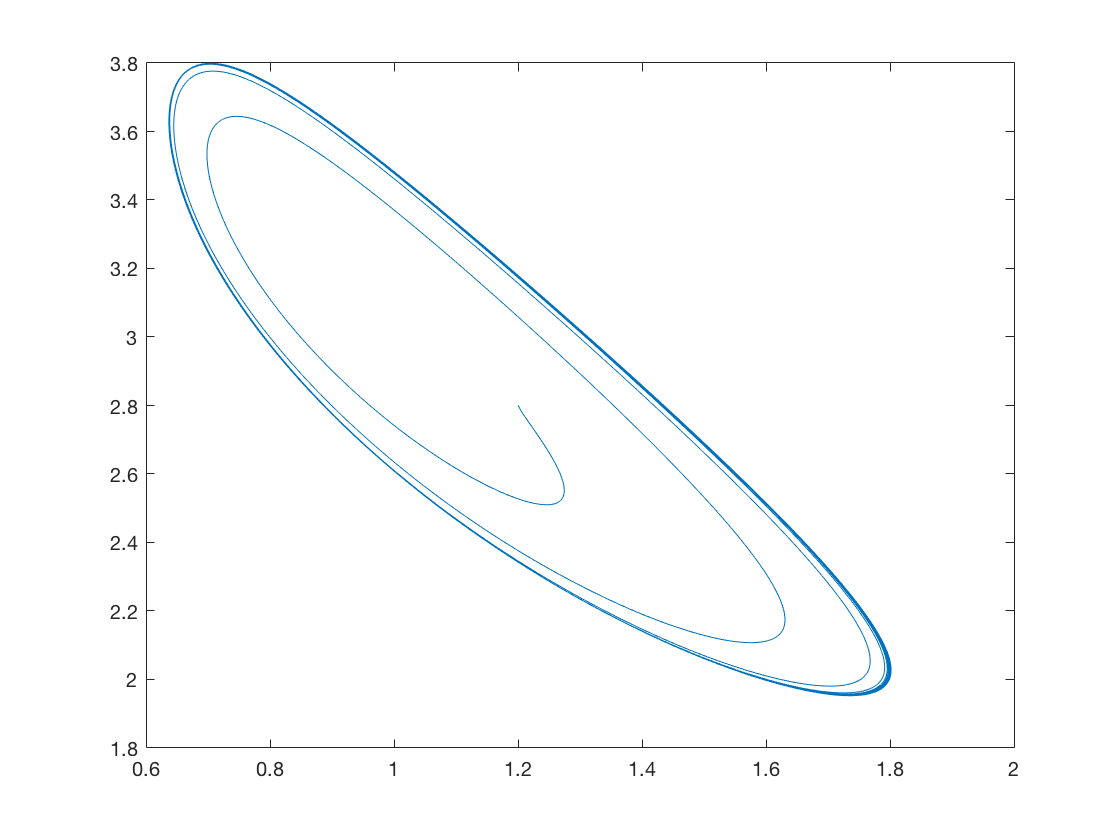

[t,y]=FDE_PI1_Im(alpha,f_fun,J_fun,t0,T,y0,h,param);
plot(y(1,:),y(2,:))

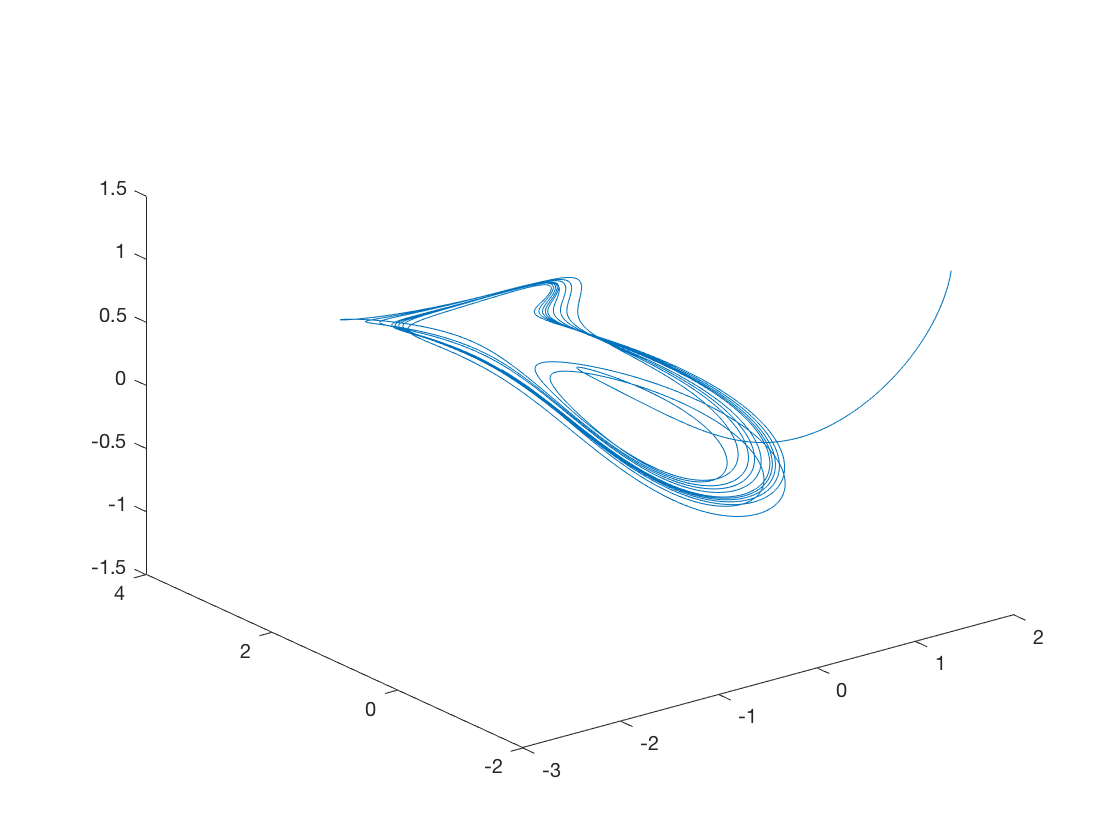

clc
clear all 
%%here is for testing the function of huwei
h=0.01;
alpha=[0.9,0.85,0.95];
param=[1,0.1,1];
y0=[2;-1;1];
f_fun=@(t,y,par)([y(3)+(y(2)-par(1))*y(1);1-par(2)*y(2)-y(1)^2;-y(1)-par(3)*y(3)]);
J_fun=@(t,y,par)([-par(1),y(1),1;...
    -2*y(1),-par(2),0;...
    -1,0,-par(3)]);
t0=0;
T=100;
[t,y]=FDE_PI1_Im(alpha,f_fun,J_fun,t0,T,y0,h,param);
plot3(y(1,:),y(2,:),y(3,:))